X = 0:0.0017:0.3;            % Length of flat plate
Xcr = 0.017;                      % Distance from the leading edge to the transition point
U = 30;                            %  Flow speed (Velocity) m/s2
P = 1.204;                            %  density of the fluid kg/m3             
u = (1.81*10^-5);                           %  Flow speed (Velocity) m/s2
Recr = ((U*P*Xcr)/u);                            %  Reynolds number at transition point
Re = ((U*P*X)/(u));            %  Reynolds number at any distance
BTcr = ((4.91*Xcr)/sqrt(Recr)) 

BTcr = 4.5318e-04

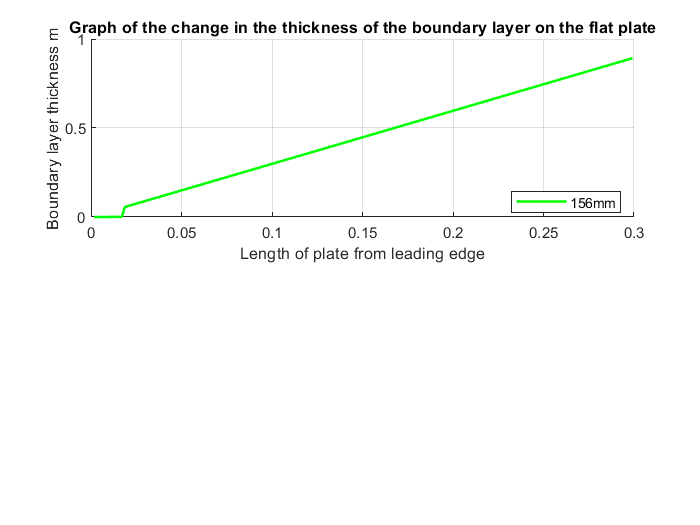


for x = 1:length(X)            % Length of flat plate
 if (X(x)<Xcr) 
  Re(x) = ((U*P*X(x))/(u)); 
    BT(x) = ((4.91*X(x))./sqrt(Re(x))); 
    % For laminar boundary layers over a flat plate, the Blasius solution to the flow governing
elseif(Xcr<(x)) && (X(x)<=0.3)
     
  BT(x) = ((0.37*X(x))./(Recr)^-0.2) + BTcr; %  Boundary Thickness at transition point

 end
end

sp1 =subplot(2,1,1); hold on; 
plot(X,BT,'g-','linewidth',1.5)
title('Graph of the change in the thickness of the boundary layer on the flat plate');    % use for title positioning
xlabel('Length of plate from leading edge'); 
ylabel('Boundary layer thickness m');                         
legend('156mm','Location','best');
grid on; 